# Draw three intersecting planes in 3D

SETUP SECTION

In this animation three planes intersect along the horizontal line: $x=y,z=5$ in three space

Uses a for loop at the end to animate the angle of view. 

The solution line flashes on ond off during the animation so it really stands out!

Just run this file to see your animation. 


clear, clc,  close all
figure

% Step 1: Enter the coefficient matrix A and the vector B for the equation A*X = B
A = [1 -1 1; -1 1 1; 1 -1 5]; % define matrix A here
B = [5; 5; 25];
AM = [A B];     % augmented matrix for the linear system
RAM = rref(AM)  % Shows solution is the line:  x=y, z=5

RAM =      1    -1     0     0
     0     0     1     5
     0     0     0     0




% Step 2: Choose POLAR or CARTESIAN coordinates
use_polar_coordinates = true % options: true (polar) or false (cartesian)

use_polar_coordinates = logical
   1


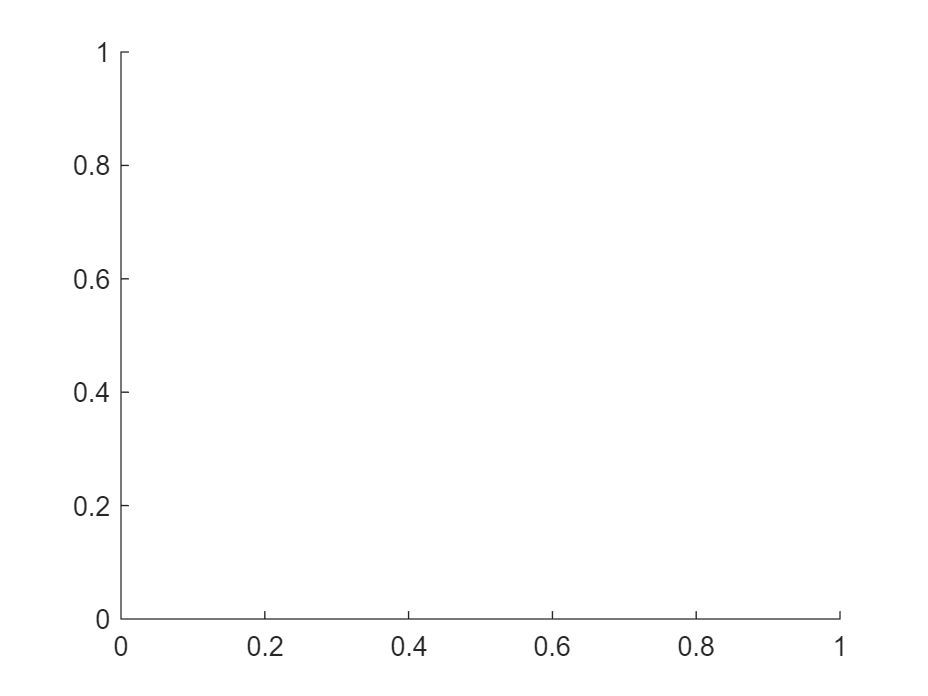


% Step 3: Choose a colormap. 
% try other colormaps such as cool, hot, hsv, prism, flag, jet, parula, lines
colormap flag

% choose preferred shading for surface plots
shading faceted % Shading methods are faceted, flat, and interp.

## * * * * * * * * * * SHOW REFERENCE OBJECTS * * * * * * * * * *

show x, y and z axes, and a reference base = disc or square in xy-plane next create the reference base over which the surfaces are plotted. this lies in the xy-plane (that is, z=0) the reference base is a disc in polar coordinates and a square in cartesian coordinates. All planes are surfaces over this reference base. 

% construct a cartesian meshgrid
% Set up a grid for each 3D plot. 
L = 5 % limit for both horizontal axes, but not the z-axis. 

L = 5

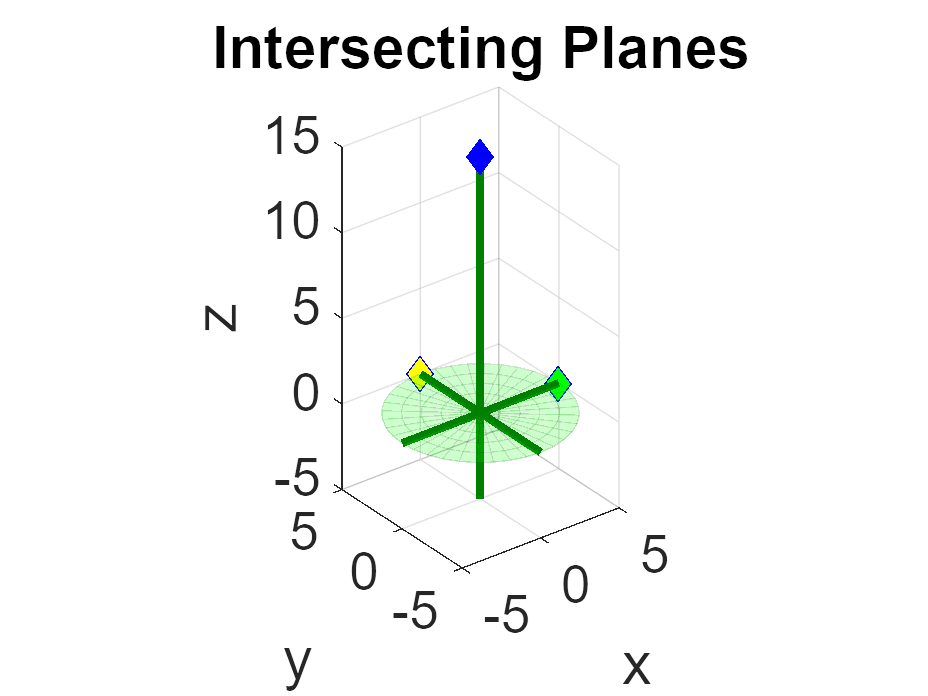

x = -L : 1 : L;  % x will range from -L to L. 
y = -L : 1 : L;  % y will range from -L to L. 
[X,Y] = meshgrid(x,y); % A grid of xy-points. (cartesian option)
Z = 0*X;

% polar coordinates will be used instead, if you set use_polar_coordinates = true
if use_polar_coordinates
    [rad,theta] = meshgrid(0:1:5, 0:2*pi/36: (2*pi) );
    X = rad.*cos(theta);
    Y = rad.*sin(theta);
    Z = 0*X;  
end

% draw the reference base in the xy-plane (it's a disc or a square)
base = surf(X, Y, Z); 
hold on
darkgreen = [0 0.5 0 ];
base.set('edgecolor', darkgreen);
base.set('facecolor', 'green');
base.set('facealpha', 0.2);  base.set('edgealpha', 0.2);

% label the axes
xlabel('x'); ylabel('y'); zlabel('z')
set(gca, 'FontSize', 20)
title('Intersecting Planes')

% control the axes limits and scaling here
axis equal
% We will set the limits for the z-axis carefully.
% different systems of equations will require different z limits
zmin = -5; zmax = 15; % these have to be set by trial and error. 
axis([-L, L, -L, L, zmin, zmax]) % set all three axis limits - we are in three space
rotate3d on % now the user can rotate the 3d plot with the mouse

% Plot the three coordinate axis in the background (as reference objects)
% the x-axis
plot3([-L,L],  [0,0], [0,0],  'color', darkgreen, 'LineWidth', 3)
% the y-axis
plot3([0,0], [-L,L], [0,0],   'color', darkgreen, 'LineWidth', 3)
% the s-axis
plot3( [0,0], [0,0], [zmin, zmax], 'color', darkgreen, 'LineWidth', 3)

% indicate positive direction for each axis with a small marker
% Add one reference marker at the tip of the positive x-axis. 
plot3( L, 0, 0, 'bd', 'MarkerSize', 9, 'MarkerFaceColor', 'green')

% Add one reference marker at the tip of the positive y-axis. 
plot3( 0, L, 0, 'bd', 'MarkerSize', 9, 'MarkerFaceColor', 'yellow')

% Add one reference marker at the tip of the positive z-axis. 
plot3( 0, 0, zmax, 'bd', 'MarkerSize', 9, 'MarkerFaceColor', 'blue')

box off % it's annoying! turn it off!

## * * * * * * * * * * DRAW THE PLANES and the SOLUTION SET!! * * * * * * * * * *

STEP 4: SHOW THE SOLUTION SET This section must be done manually if the equations are changed. The solutions consist of the line where the three planes intersect. 

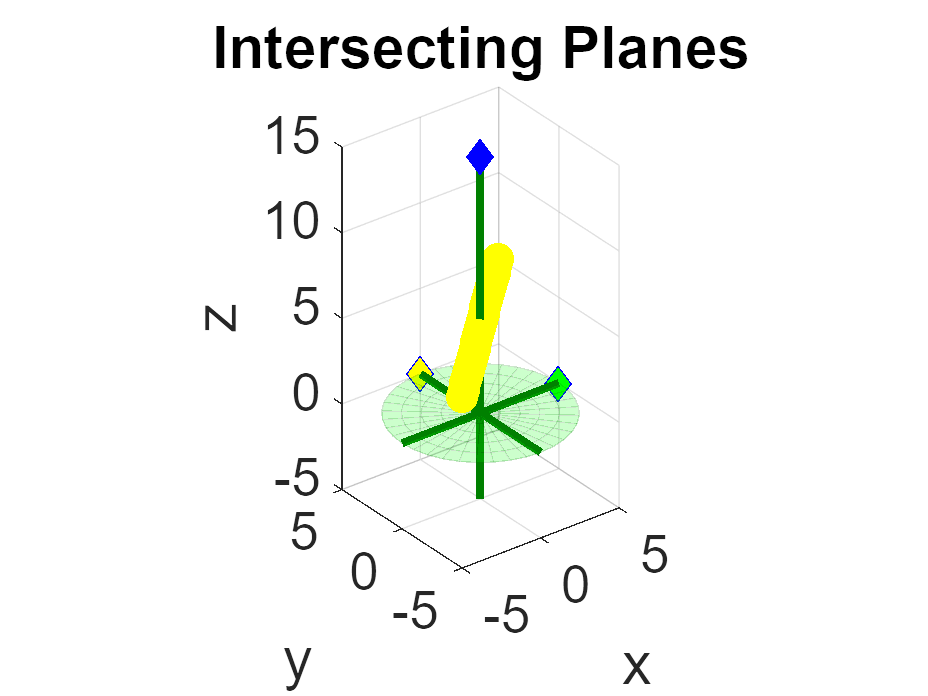

y=-L: 0.5 :L;  % in the default example, the variable y is free
% SOLUTION SET: x = y, y = free, z = 5 is the solution line. 

x = y; z = 5*ones(size(y));
line_of_solutions = plot3(x, y, z, 'blue', 'LineWidth', 4);
set(line_of_solutions, 'LineStyle', '-', 'MarkerFaceColor', 'yellow', 'MarkerEdgeColor', 'none',  'Marker', 'o', 'MarkerSize', 12)

## 1. Equation for the first plane. ax + by + cz = d

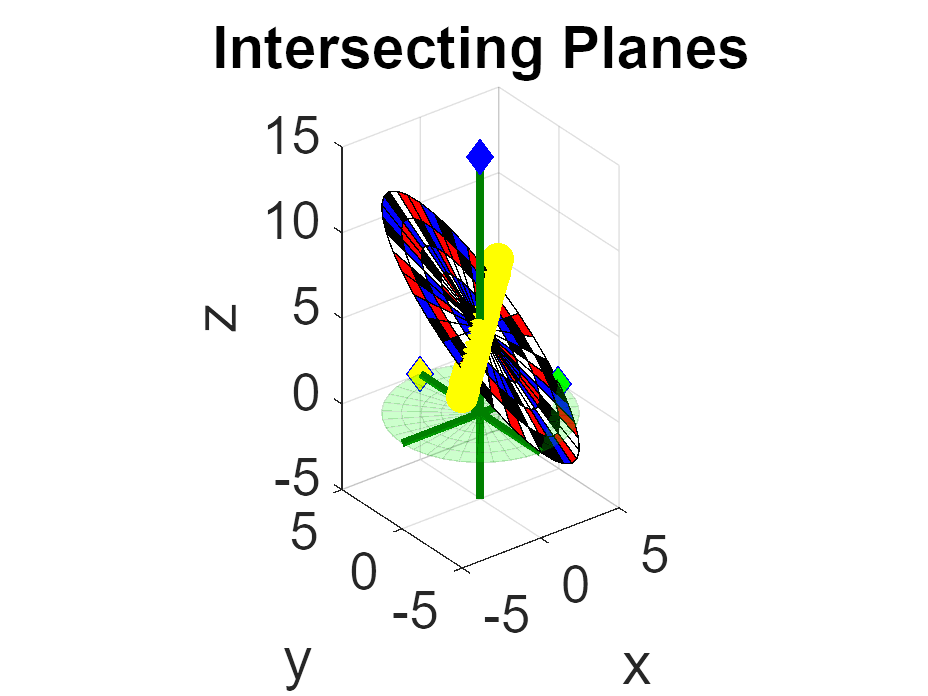

a = A(1, 1);  b = A(1, 2);  c =  A(1, 3); d = B(1);
Z = (d - a * X - b * Y)/c;
p1 = surf(X,Y,Z);  % Draw the plane defined by the first equation.

## 2. Equation for the second plane.

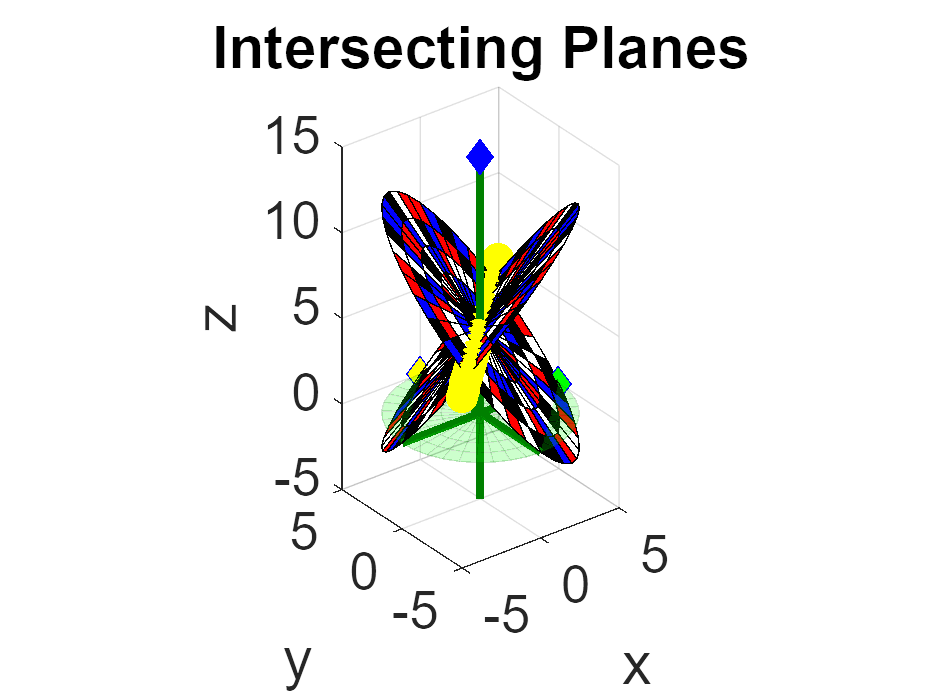

a = A(2, 1);  b = A(2, 2);  c =  A(2, 3); d = B(2);
Z = (d - a * X - b * Y)/c;
p2 = surf(X,Y,Z); % Draw the plane defined by the second equation.

## 3. Equation for the third plane.

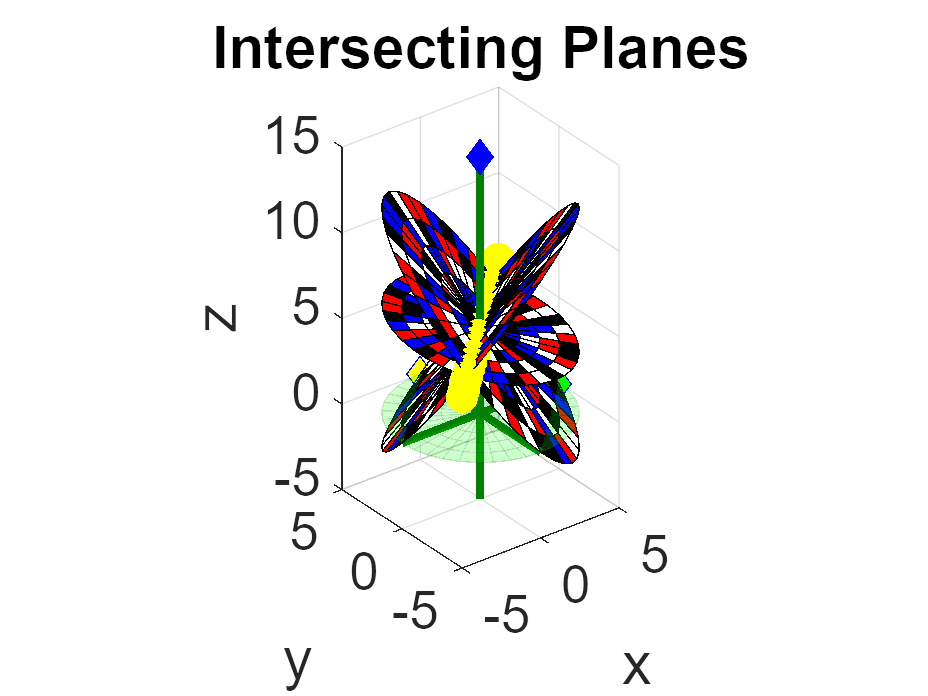

a = A(3, 1);  b = A(3, 2);  c =  A(3, 3); d = B(3);
Z=(d - a * X - b * Y)/c;
p3 = surf(X,Y,Z); % Draw the plane defined by the second equation.

## Adjust colors and transparency to enhace the animation

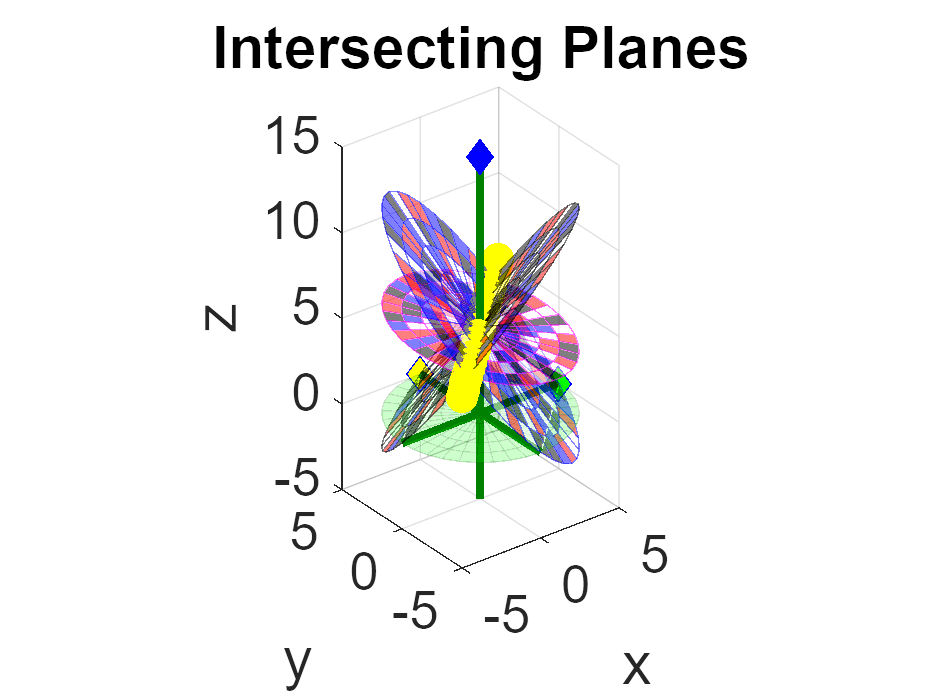

p1.set('facealpha', 0.50)  % Make the surface plots partially transparent. 
p2.set('facealpha', 0.50)  % Make the surface plots partially transparent. 
p3.set('facealpha', 0.50)   % Make the surface plots partially transparent. 
p1.set('edgecolor', 'b');  p2.set('edgecolor', 'k');  p3.set('edgecolor', 'm');
p1.set('edgealpha', 0.5);  p2.set('edgealpha', 0.5);  p3.set('edgealpha', 0.5);


% C = p3.get('CData'); p3.set('CData', -C)
% p2.set('CData', -10+ 0*C)

## Spin the figure about the z-axis to creat an animation offering multiple views.

Yellow markers, representing solution points flash on and off. 

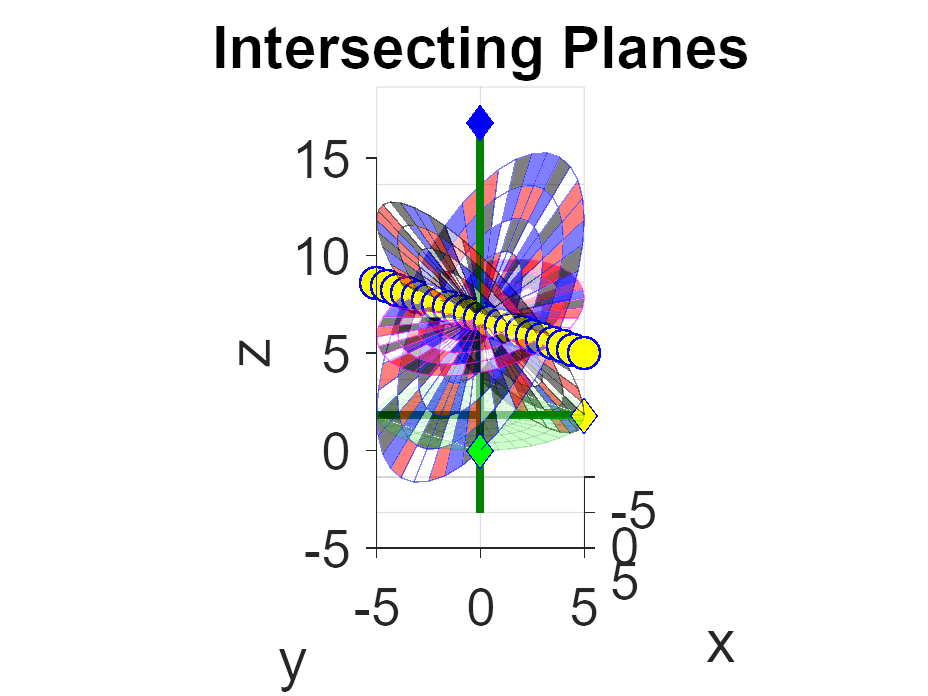

N = 2; % Number of complete revolutions of the azimuth. Elevation fixed at 20. 
for k =0:1:360*N
    view([90 + k, 20])  % view( [azimuth, elevation] )
    pause(0.05)
    if mod(k,2)
        set(line_of_solutions, 'LineStyle', '-', 'Marker', 'None ', 'Color', 'blue', 'Linewidth', 6)
    else       
        set(line_of_solutions, 'LineStyle', 'None', 'MarkerEdgeColor', 'blue', 'MarkerFaceColor', 'yellow', 'Marker', 'o', 'MarkerSize', 12, 'Linewidth', 1)
    end
end